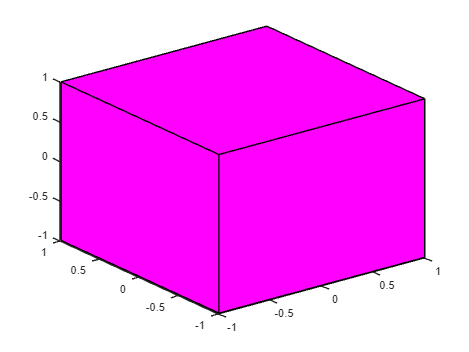


verticesCube = [
    -1, 1, 1, -1, -1, 1, 1, -1;
    -1, -1, 1, 1, -1, -1, 1, 1;
    -1, -1, -1, -1, 1, 1, 1, 1;
    1, 1, 1, 1, 1, 1, 1, 1
    ];

facesCube = [
    1, 2, 6, 5;
    2, 3, 7, 6;
    3, 4, 8, 7;
    4, 1, 5, 8;
    1, 2, 3, 4;
    5, 6, 7, 8
    ];

moveCamera = [
    1, 0, 0, 0;
    0, 1, 0, 0;
    0, 0, 1, 0;
    0, 0, 0, 1;
]; 

phi = 0;
teta = 0;

rotateYMatrix = [
    cos(teta), 0, sin(teta), 0;
    0, 1, 0, 0;
    -sin(teta), 0, cos(teta), 0;
    0, 0, 0, 1
    ];

rotateZMatrix = [
    cos(phi), -sin(phi), 0, 0;
    sin(phi), cos(phi), 0, 0;
    0, 0, 1, 0;
    0, 0, 0, 1
    ];
rotateXMatrix = [
    1, 0, 0, 0;
    0, cos(phi), -sin(phi), 0;
    0, sin(phi), cos(phi), 0;
    0, 0, 0, 1
    ];

newVertices = (rotateYMatrix * moveCamera)^(-1) * verticesCube;

DrawShape (verticesCube, facesCube, 'm')
view(3);

function DrawShape(vertices, faces, color)
    patch('Vertices', (vertices(1:3,:)./vertices(4,:))','Faces', faces, 'FaceColor', color);

end